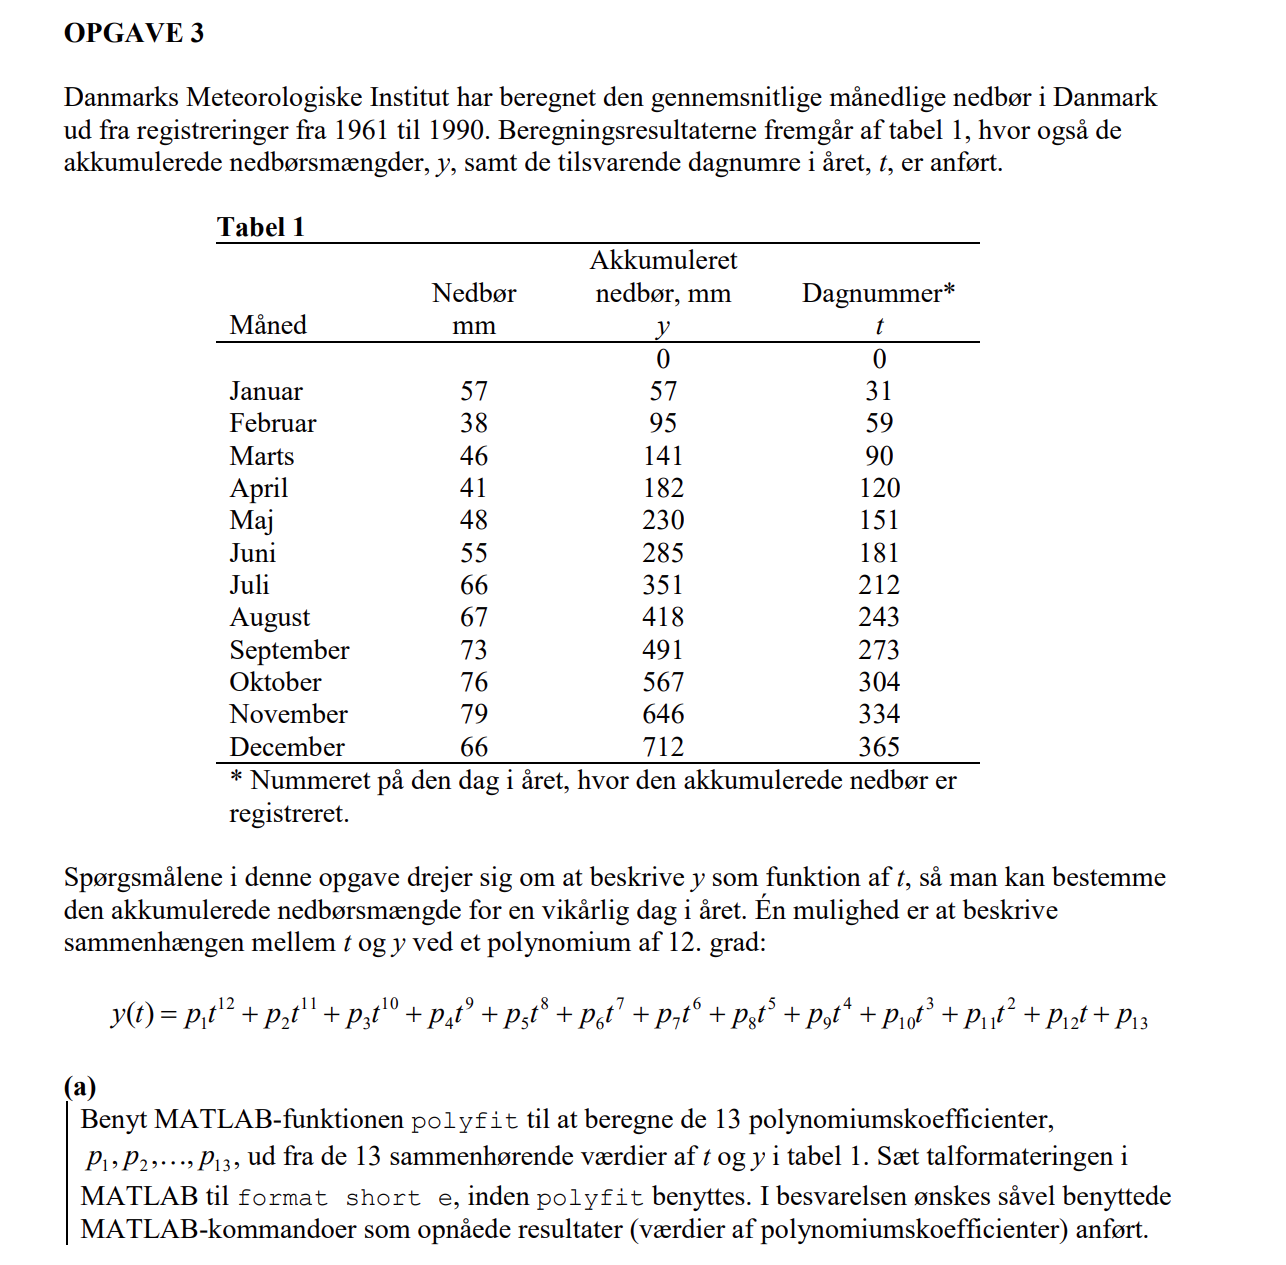

format short e %formater som anvist i opgaven. 
%data
y = [0 57 95 141 182 230 285 351 418 491 567 646 712]';
t = [0 31 59 90 120 151 181 212 243 273 304 334 365]';
P_fit = polyfit(t,y,12)'; %bruger polyfit til at lave et 12grad polynomie der går igennem alle data punkter

T = table(P_fit, t, y); %Laver en tabel så det er nemt læsligt.
disp(T)

       P_fit           t             y     
    ___________    __________    __________

    -6.9696e-24    0.0000e+00    0.0000e+00
     1.5001e-20    3.1000e+01    5.7000e+01
    -1.4240e-17    5.9000e+01    9.5000e+01
     7.8506e-15    9.0000e+01    1.4100e+02
    -2.7853e-12    1.2000e+02    1.8200e+02
     6.6575e-10    1.5100e+02    2.3000e+02
    -1.0901e-07    1.8100e+02    2.8500e+02
     1.2176e-05    2.1200e+02    3.5100e+02
    -9.0402e-04    2.4300e+02    4.1800e+02
     4.2183e-02    2.7300e+02    4.9100e+02
    -1.1051e+00    3.0400e+02    5.6700e+02
     1.3847e+01    3.3400e+02    6.4600e+02
     4.5609e-08    3.6500e+02    7.1200e+02



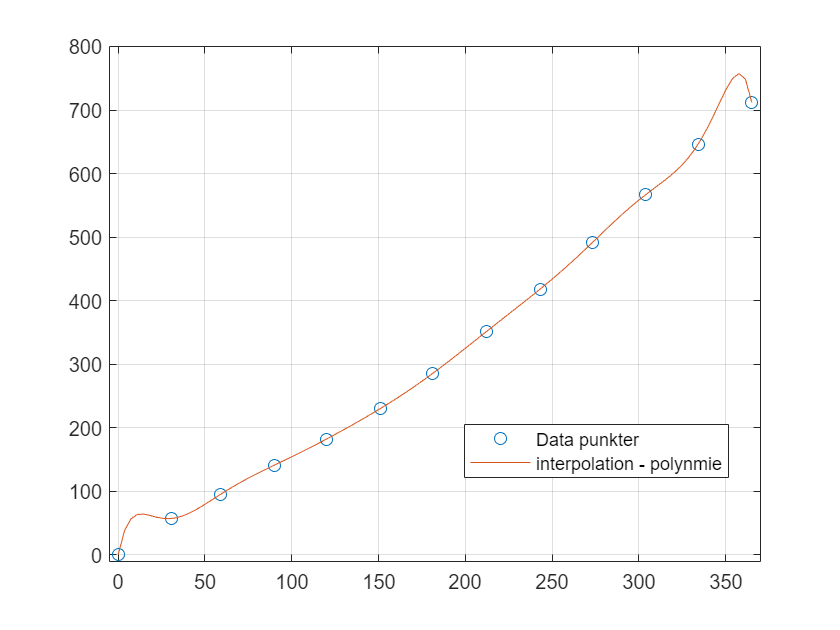

%data en plottes
tt = linspace(0,365); %fordeler 100 værdiger fra 0 til 365
yy = polyval(P_fit,tt); %giver de interpolatede y værdier
plot(t,y,'o', 'DisplayName', 'Data punkter')
hold on
plot(tt,yy, 'DisplayName', 'interpolation - polynmie')
legend('location', 'best')
xlim([-5, 370]) % Plotte begrænses
ylim([-10,800])
grid
hold off

vi kan se at polynomiet går igennem alle punkterne hvilket er en god start men at fra først til anden værdig og fra anden sidste til sidste værdig får vi nogle lidt underlige værdiger som nok ikke er korrekte. Matlab afgiver også en advarsel da polynomiet er støre en et 4 grads polynomie

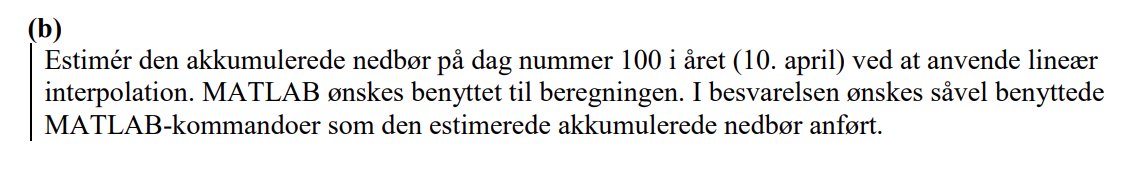

format shortG %lidt mere læsligt 
ned_d100 = interp1(t,y,100,"linear") %100 kommer af det det er for dag 100

ned_d100 =        154.67


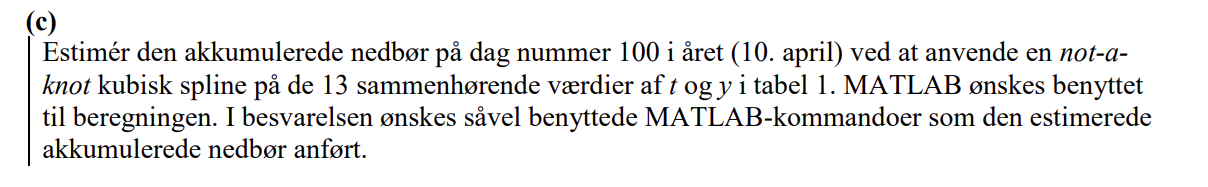

ned_d100_spline = spline(t,y,100) %der interpoleres med spline 

ned_d100_spline =        154.87


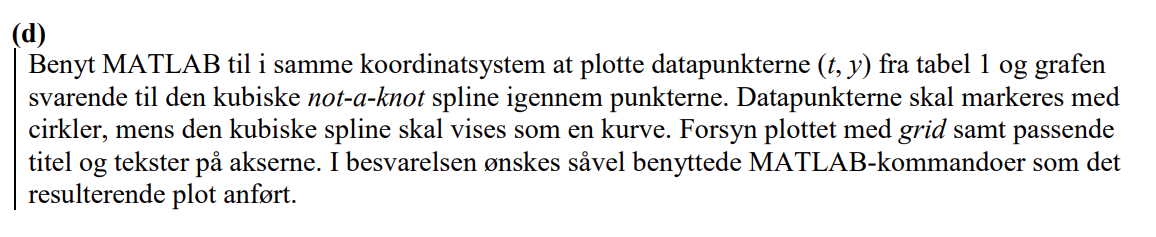

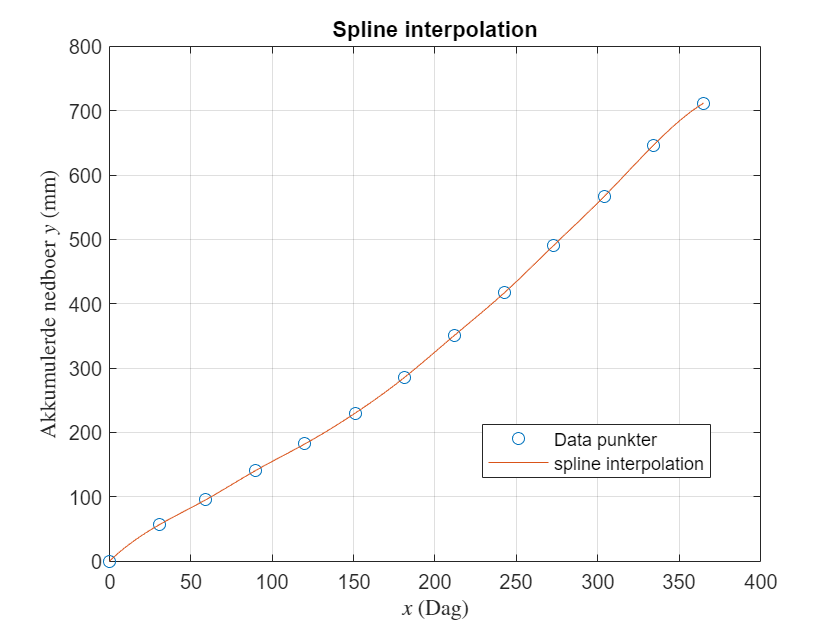

ned_spl = spline(t,y,tt); % denne gang bruges linspace fra tidligere.
%plot
plot(t,y,'o', 'DisplayName', 'Data punkter')
hold on
plot(tt,ned_spl, 'DisplayName', 'spline interpolation') % interpolation med spline plottes

% formalier
legend('location', 'best')
title('Spline interpolation')
xlabel('$x$ (Dag)', 'interpreter', 'latex')
ylabel('Akkumulerde nedboer $y$ (mm)', 'interpreter', 'latex')
grid
hold off

Dette ser nået mere korrekt ud. 

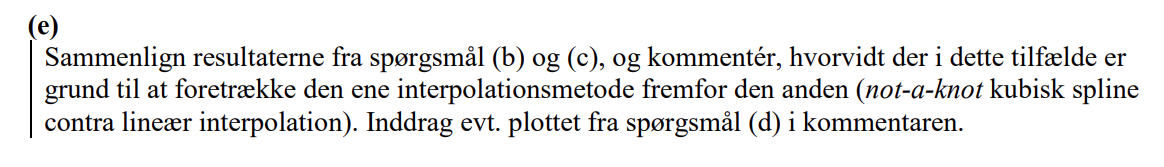

ned_int_lin = interp1(t,y,tt,"linear"); %interpolation interp1 lineær laves med linspacen xx

afvigelse = (ned_d100_spline-ned_d100)/ned_d100*100

afvigelse =       0.13334


En afvigelse på 0.13% så  det gør nok ikke den store forskel om det er den ene eller den anden. Der kan dog argumenteres for at spline er en smugle mere korrekt da vi kan med øjet se i grafen fra opgave d at dataen ikke er helt linær. 

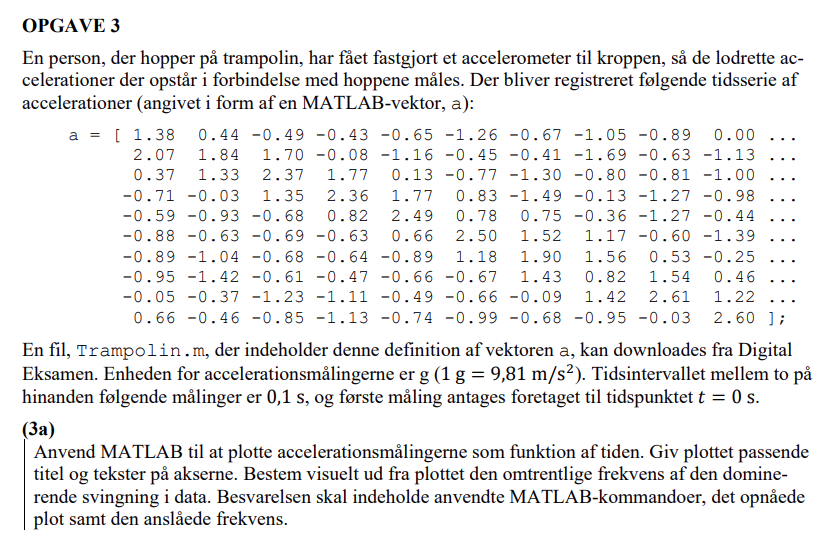

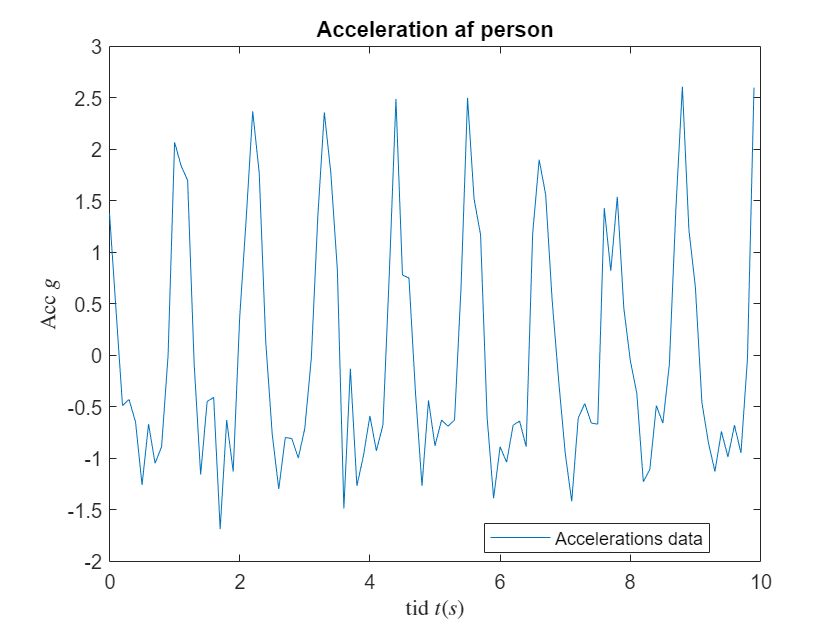

clear
a = [ 1.38 0.44 -0.49 -0.43 -0.65 -1.26 -0.67 -1.05 -0.89 0.00 ...
2.07 1.84 1.70 -0.08 -1.16 -0.45 -0.41 -1.69 -0.63 -1.13 ...
0.37 1.33 2.37 1.77 0.13 -0.77 -1.30 -0.80 -0.81 -1.00 ...
-0.71 -0.03 1.35 2.36 1.77 0.83 -1.49 -0.13 -1.27 -0.98 ...
-0.59 -0.93 -0.68 0.82 2.49 0.78 0.75 -0.36 -1.27 -0.44 ...
-0.88 -0.63 -0.69 -0.63 0.66 2.50 1.52 1.17 -0.60 -1.39 ...
-0.89 -1.04 -0.68 -0.64 -0.89 1.18 1.90 1.56 0.53 -0.25 ...
-0.95 -1.42 -0.61 -0.47 -0.66 -0.67 1.43 0.82 1.54 0.46 ...
-0.05 -0.37 -1.23 -1.11 -0.49 -0.66 -0.09 1.42 2.61 1.22 ...
0.66 -0.46 -0.85 -1.13 -0.74 -0.99 -0.68 -0.95 -0.03 2.60 ]; 
% ^data

t = 0:0.1:(length(a)/10-0.1); %data for tiden dimensioneres

plot(t,a, 'DisplayName', 'Accelerations data') %plot

legend('location', 'best')
title('Acceleration af person')
xlabel('tid $t(s)$', 'interpreter', 'latex')
ylabel('Acc $g$', 'interpreter', 'latex')

%Frekevens estimeres
toppe = 9; % 9 toppe tælles over 10 sekunder
freq = toppe/10 %frekvensen 

freq =           0.9


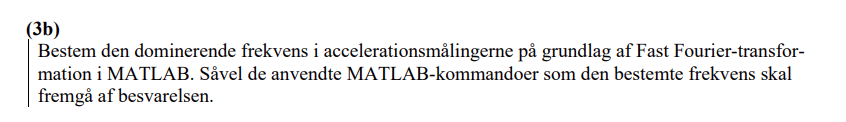

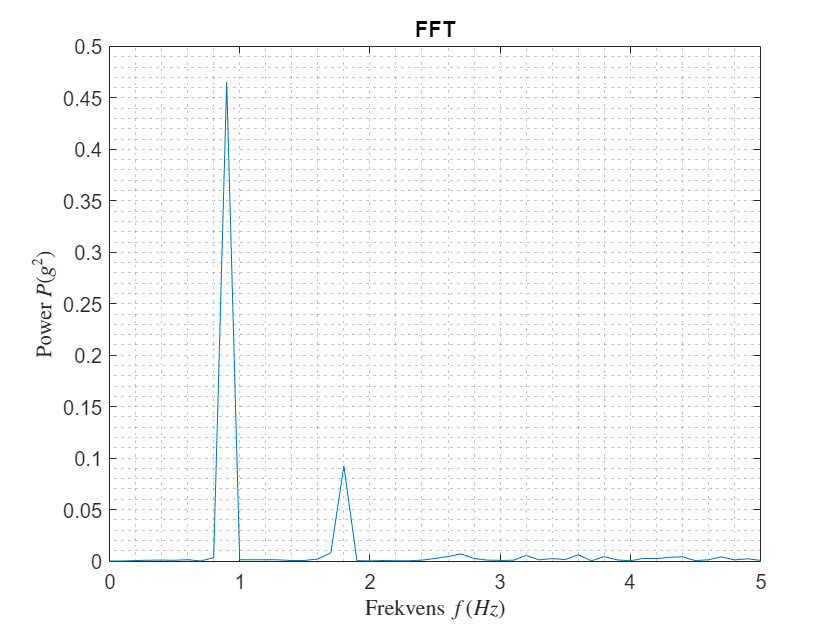

dt = 0.1;                   % Samplingsinterval (s)
n = length(a);              % Antal samplinger %
T = n*dt;                   % Signallængde (s) 
A = fft(a)/n;               % FFT af a (mm)
fs = 1/dt;                  % Samplingsfrekvens (Hz) 
fmax = fs/2;                % Maks frekvens (Hz)
df = 1/T;                   % Frekvensstep (Hz)
f = (0:n-1)*df;             % Frekvensvektor (Hz) % alle frekvensskridt der køres igennem
P = real(A).^2 + imag(A).^2;% Powervektor (mm^2) % 
plot(f,P);                   % Plot af powerspektrum 
xlim([0 fmax]);             % Afgræns frekvensakse 

% Formalier
title('FFT')
xlabel('Frekvens $f(Hz)$', 'interpreter', 'latex')
ylabel('Power $P(g^2)$', 'interpreter', 'latex')
grid('minor')

result = find(P==max(P)) % finder positionen(index) hvor værdigen er højest i vektoren

result =     10    92


f(result(1)) %frekvensen er 0.9Hz 

ans =           0.9
